setup,
addpath('Q:\dataAvendano_Apr5\CARACTERIZACION');

# Phantom 1: 8% gelatin, 2% cornstarch

## Acquisition 1: Just water

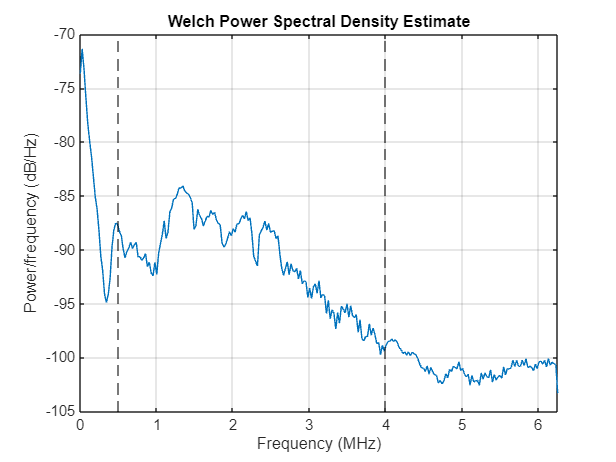

% Set as desired
acq1 = [20 21 22];
acq2 = [17,18,19];
BW = [0.5e6 4e6]; % Bandwidth for basic filtering

% Loading data
ii = acq1(1);
data_r = readmatrix(sprintf('TEK000%d.CSV', ii),"Range", "A17:B20016");
t = data_r(:,1); 
volt = data_r(:,2);
N = length(t);
Fs = 1/((t(end)-t(1))/N);

% Displaying spectrum
figure, 
pwelch(volt,400,200,512,Fs)
hold on
xline(BW/1e6, 'k--')

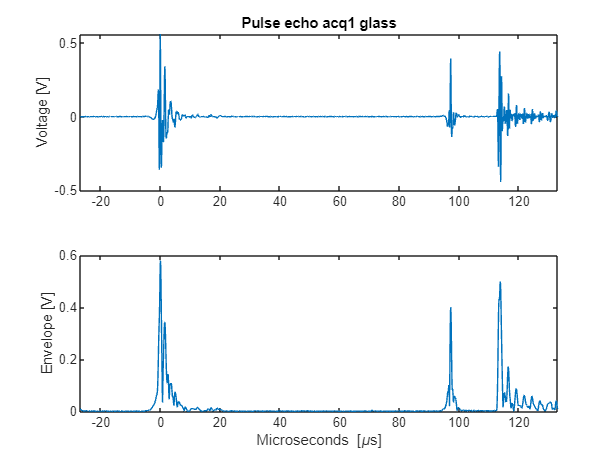

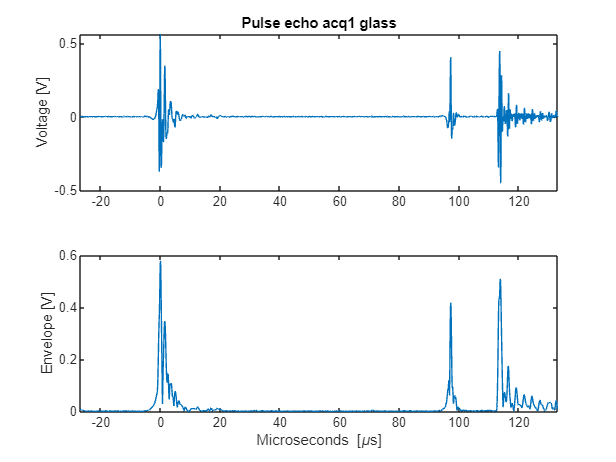

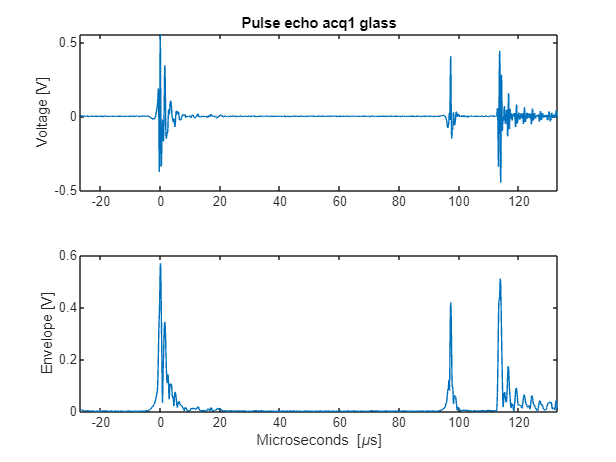

for ii = acq1
    % Loading data
    data_r = readmatrix(sprintf('TEK000%d.CSV', ii),"Range", "A17:B20016");
    t = data_r(:,1);    %[s]
    volt = data_r(:,2); %[V]
    N = length(t);
    Fs = 1/((t(end)-t(1))/N); % sampling frequency [samples/s]
    
    % Filtering
    [b,a] = butter(2,BW/Fs,"bandpass");
    volt = filtfilt(b,a,volt);
    envol_ref= hilbert(volt);
    
    % Plotting
    xLimits = [t(1),t(end)] *1e6;
    figure,
    tiledlayout(2,1)
    nexttile,
    plot (t*1e6,volt), 
    ylabel('Voltage [V]'),
    xlim (xLimits), 
    title ('Pulse echo acq1 glass')
    nexttile,
    plot(t*1e6,abs(envol_ref)),
    xlim (xLimits);
    ylabel('Envelope [V]'),
    xlabel ('Microseconds [\mus]')
end

% Set according to plot and temperature measurement
cWater = 1482.97;  
tPlexi = 97.2e-6;  
dPlexi = cWater*tPlexi/2

dPlexi = 0.0721

## Acquisition 2: Water and gelatin

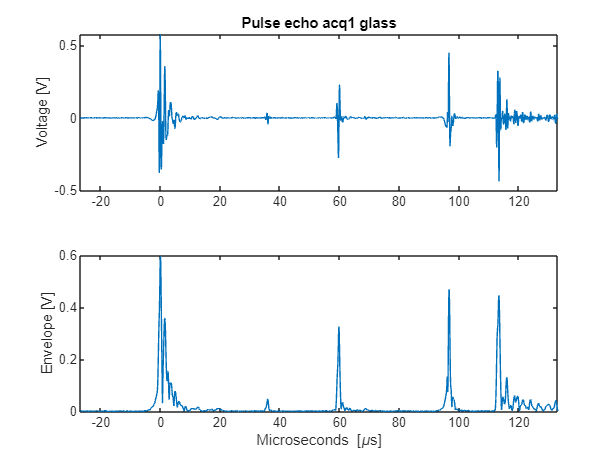

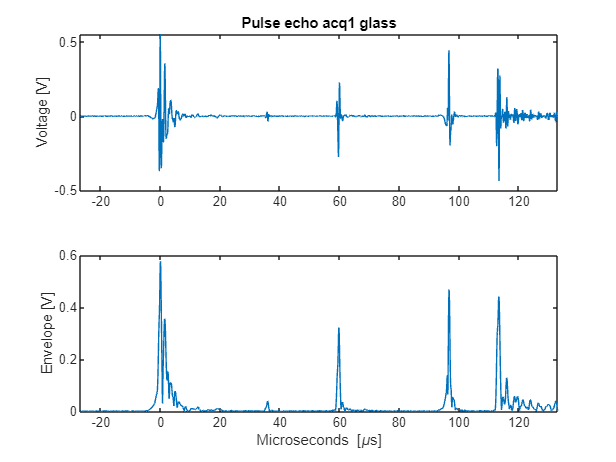

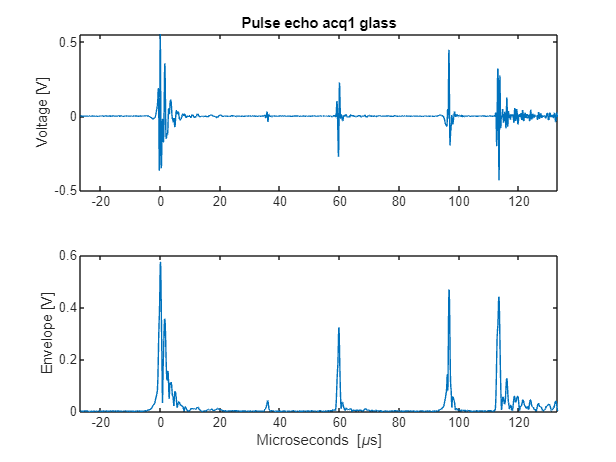

for ii = acq2
    % Loading data
    data_r = readmatrix(sprintf('TEK000%d.CSV', ii),"Range", "A17:B20016");
    t = data_r(:,1);    %[s]
    volt = data_r(:,2); %[V]
    N = length(t);
    Fs = 1/((t(end)-t(1))/N); % sampling frequency [samples/s]
    
    % Filtering
    [b,a] = butter(2,BW/Fs,"bandpass");
    volt = filtfilt(b,a,volt);
    envol_ref= hilbert(volt);
    
    % Plotting
    xLimits = [t(1),t(end)] *1e6;
    figure,
    tiledlayout(2,1)
    nexttile,
    plot (t*1e6,volt), 
    ylabel('Voltage [V]'),
    xlim (xLimits), 
    title ('Pulse echo acq1 glass')
    nexttile,
    plot(t*1e6,abs(envol_ref)),
    xlim (xLimits);
    ylabel('Envelope [V]'),
    xlabel ('Microseconds [\mus]')
end

Set the times of the peak positions

t1 = 35.92e-6;
t2 = 59.76e-6;
t3 = 96.64e-6;

dWater = cWater*t1/2 + cWater*(t3-t2)/2

dWater = 0.0540

dPhantom = dPlexi - dWater

dPhantom = 0.0181

cPhantom = dPhantom/(t2-t1)*2

cPhantom = 1.5178e+03

# Phantom 2: Agar

## Acquisition 1: Just water

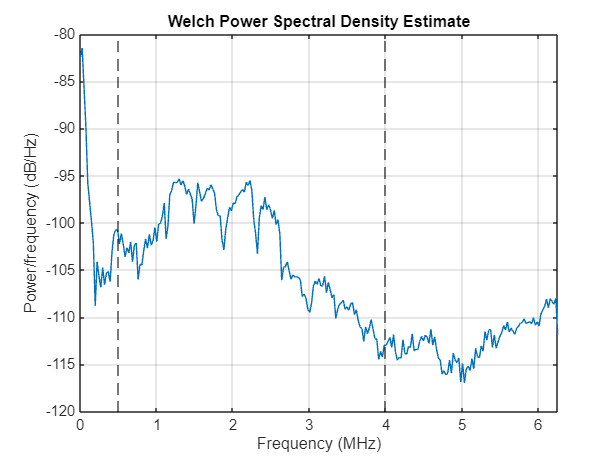

% Set as desired
acq1 = [36,37,38];
acq2 = [33,34,35];
BW = [0.5e6 4e6];

% Loading data
ii = acq1(1);
data_r = readmatrix(sprintf('TEK000%d.CSV', ii),"Range", "A17:B20016");
t = data_r(:,1); 
volt = data_r(:,2);
N = length(t);
Fs = 1/((t(end)-t(1))/N);

% Displaying spectrum
figure, 
pwelch(volt,400,200,512,Fs)
hold on
xline(BW/1e6, 'k--')

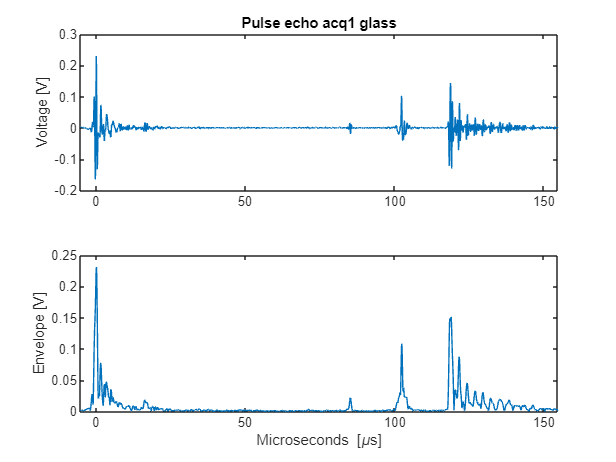

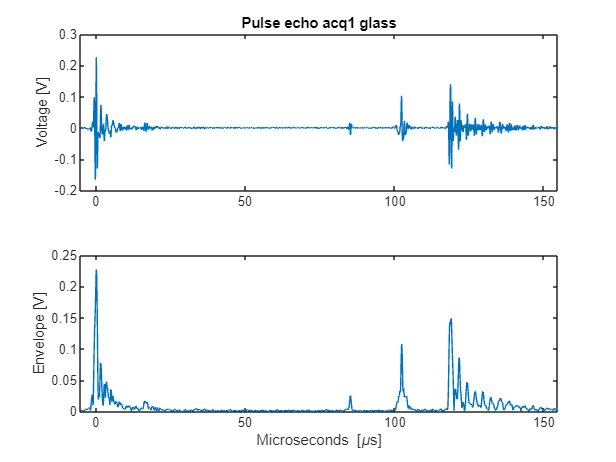

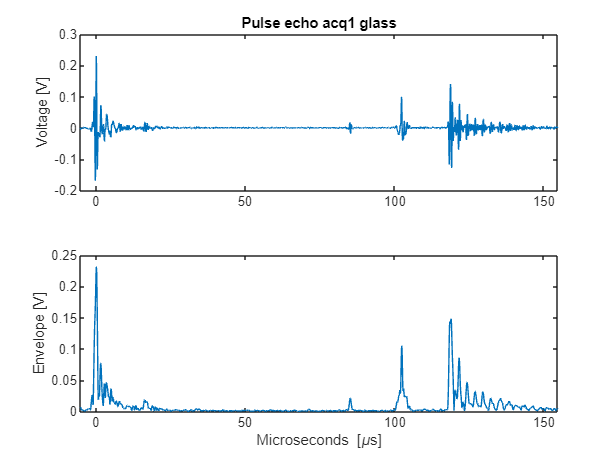

for ii = acq1
    % Loading data
    data_r = readmatrix(sprintf('TEK000%d.CSV', ii),"Range", "A17:B20016");
    t = data_r(:,1);    %[s]
    volt = data_r(:,2); %[V]
    N = length(t);
    Fs = 1/((t(end)-t(1))/N); % sampling frequency [samples/s]
    
    % Filtering
    [b,a] = butter(2,BW/Fs,"bandpass");
    volt = filtfilt(b,a,volt);
    envol_ref= hilbert(volt);
    
    % Plotting
    xLimits = [t(1),t(end)] *1e6;
    figure,
    tiledlayout(2,1)
    nexttile,
    plot (t*1e6,volt), 
    ylabel('Voltage [V]'),
    xlim (xLimits), 
    title ('Pulse echo acq1 glass')
    nexttile,
    plot(t*1e6,abs(envol_ref)),
    xlim (xLimits);
    ylabel('Envelope [V]'),
    xlabel ('Microseconds [\mus]')
end

% Set according to plot and temperature measurement
cWater = 1483.275;  
tPlexi = 102.4e-6;  
dPlexi = cWater*tPlexi/2

dPlexi = 0.0759

## Acquisition 2: Water and gelatin

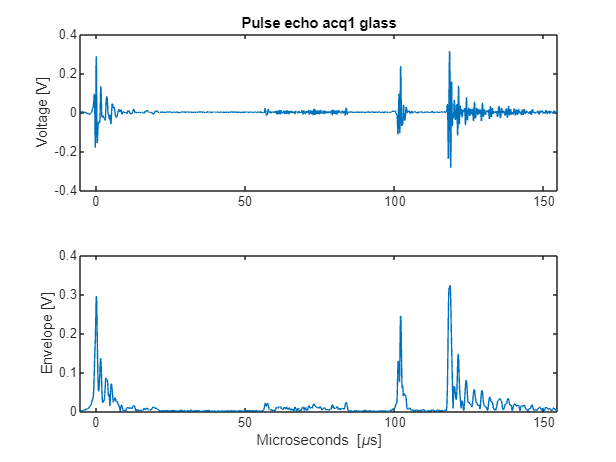

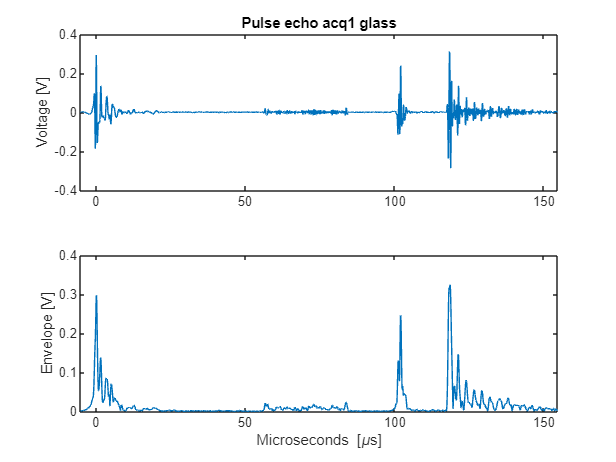

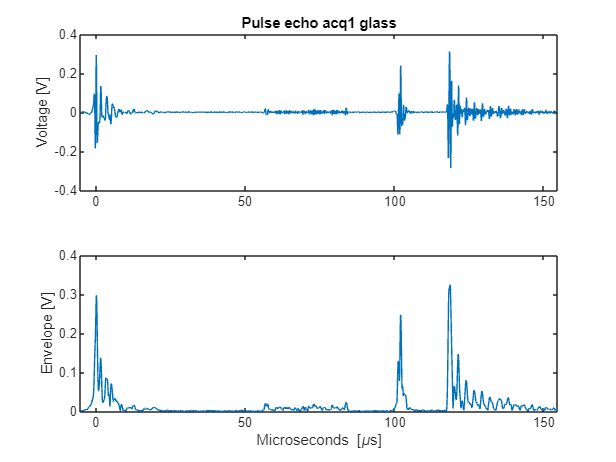

for ii = acq2
    % Loading data
    data_r = readmatrix(sprintf('TEK000%d.CSV', ii),"Range", "A17:B20016");
    t = data_r(:,1);    %[s]
    volt = data_r(:,2); %[V]
    N = length(t);
    Fs = 1/((t(end)-t(1))/N); % sampling frequency [samples/s]
    
    % Filtering
    [b,a] = butter(2,BW/Fs,"bandpass");
    volt = filtfilt(b,a,volt);
    envol_ref= hilbert(volt);
    
    % Plotting
    xLimits = [t(1),t(end)] *1e6;
    figure,
    tiledlayout(2,1)
    nexttile,
    plot (t*1e6,volt), 
    ylabel('Voltage [V]'),
    xlim (xLimits), 
    title ('Pulse echo acq1 glass')
    nexttile,
    plot(t*1e6,abs(envol_ref)),
    xlim (xLimits);
    ylabel('Envelope [V]'),
    xlabel ('Microseconds [\mus]')
end

Set the times of the peak positions

t1 = 56.72e-6;
t2 = 83.76e-6;
t3 = 102.08e-6;

dWater = cWater*t1/2 + cWater*(t3-t2)/2

dWater = 0.0557

dPhantom = dPlexi - dWater

dPhantom = 0.0203

cPhantom = dPhantom/(t2-t1)*2

cPhantom = 1.5008e+03